# Лабораторна робота №3

Яковець А., варіант 15

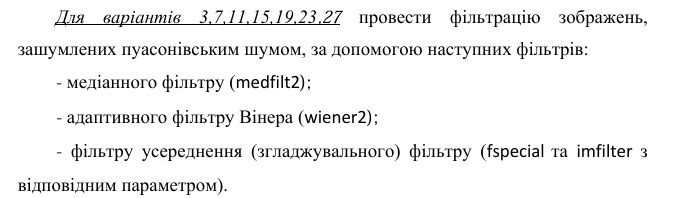

1) Отримати з файлу mri.mat зріз черепної коробки людини та збільшити 

отримане зображення вдвічі. 

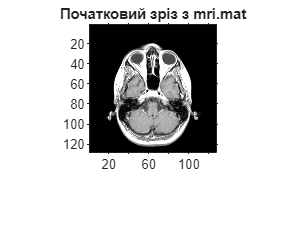

clear
clc
close all
load mri
D = squeeze(D);          % прибираємо зайві одиничні розмірності
slice_num = 5;           % номер зрізу
I = D(:,:,slice_num);    % беремо один зріз, всі ел. по коорд.

figure
imshow(I,[]) % [] автоматичний підбір потрібної яксравості
title('Початковий зріз з mri.mat')
axis on
colormap(map)

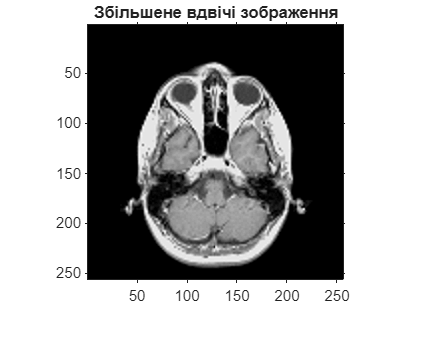



% збільшуємо зображення
I2 = imresize(I,2);
figure
imshow(I2,[])
title('Збільшене вдвічі зображення')
axis on
colormap(map)

2) Застосувати до отриманого збільшеного зображення різні способи  підвищення яскравості (histeq, imadjust, adapthisteq). 

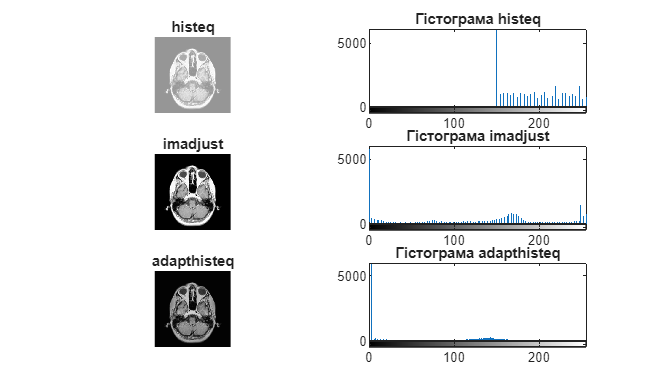

I_histeq = histeq(I2);
I_imadjust = imadjust(I2);
I_adapthisteq = adapthisteq(I2);

figure
subplot(3,2,1)
imshow(I_histeq)
title('histeq')
subplot(3,2,2)
imhist(I_histeq)
title('Гістограма histeq')

subplot(3,2,3)
imshow(I_imadjust)
title('imadjust')
subplot(3,2,4)
imhist(I_imadjust)
title('Гістограма imadjust')

subplot(3,2,5)
imshow(I_adapthisteq)
title('adapthisteq')
subplot(3,2,6)
imhist(I_adapthisteq)
title('Гістограма adapthisteq')

3) Провести обробку найкращого із зображень, отриманих у п.2),  підібравши оптимальну комбінацію цифрових фільтрів та вивести його у псевдокольорі. Для наочності порівняння  в різні підвікна одного графічного  вікна виводити отримані зображення та їхні гістограми з пояснювальними  надписами.

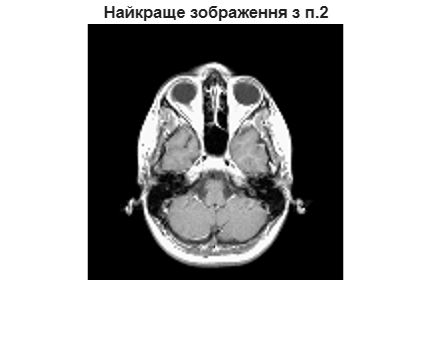

I_best = I_imadjust;
figure
imshow(I_best)
title('Найкраще зображення з п.2')

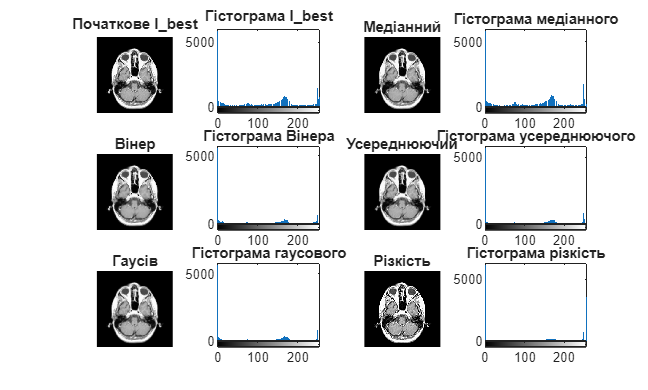


% Застосування цифрових фільтрів

% 1. Медіанний фільтр
I_median = medfilt2(I_best);

% 2. Адаптивний фільтр Вінера
I_wiener = wiener2(I_best,[5 5]);

% 3. Згладжувальний усереднюючий фільтр
h_avg = fspecial('average',[3 3]); % створюєм усереднюючий фільтр 3*3 (матриця)
I_average = imfilter(I_best,h_avg,'replicate'); %заст. до всього зобр., крайні пікселі дублюєм

% 4. Гаусів згладжувальний фільтр
h_gauss = fspecial('gaussian',[5 5],1);
I_gauss = imfilter(I_best,h_gauss,'replicate');

% 5. Підвищення різкості
h_unsharp = fspecial('unsharp');
I_unsharp = imfilter(I_best,h_unsharp,'replicate');

% 6. Виділення контурів Превітта
h_prewitt = 2 * fspecial('prewitt');
I_prewitt = imfilter(I_best,h_prewitt,'replicate');

% 7. Виділення контурів Собеля
h_sobel = 2 * fspecial('sobel');
I_sobel = imfilter(I_best,h_sobel,'replicate');

% 8. Лапласіан Гаусса
h_log = fspecial('log',[5 5],0.1);
I_log = imfilter(I_best,h_log,'replicate');

% 9. Комбінований варіант
I_combined = imadjust(I_average + I_prewitt);

% 10. Псевдоколір
pseudo_img = ind2rgb(uint8(I_best), jet(256));

figure
subplot(3,4,1)
imshow(I_best,[])
title('Початкове I\_best')

subplot(3,4,2)
imhist(I_best)
title('Гістограма I\_best')

subplot(3,4,3)
imshow(I_median,[])
title('Медіанний')

subplot(3,4,4)
imhist(I_median)
title('Гістограма медіанного')

subplot(3,4,5)
imshow(I_wiener,[])
title('Вінер')

subplot(3,4,6)
imhist(I_wiener)
title('Гістограма Вінера')

subplot(3,4,7)
imshow(I_average,[])
title('Усереднюючий')

subplot(3,4,8)
imhist(I_average)
title('Гістограма усереднюючого')


subplot(3,4,9)
imshow(I_gauss,[])
title('Гаусів')

subplot(3,4,10)
imhist(I_gauss)
title('Гістограма гаусового')

subplot(3,4,11)
imshow(I_unsharp,[])
title('Різкість')


subplot(3,4,12)
imhist(I_unsharp)
title('Гістограма різкість')

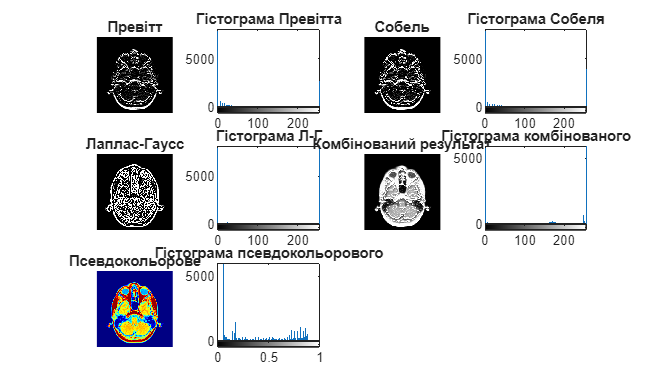



figure
subplot(3,4,1)
imshow(I_prewitt,[])
title('Превітт')

subplot(3,4,2)
imhist(I_prewitt)
title('Гістограма Превітта')

subplot(3,4,3)
imshow(I_sobel,[])
title('Собель')


subplot(3,4,4)
imhist(I_sobel)
title('Гістограма Собеля')

subplot(3,4,5)
imshow(I_log,[])
title('Лаплас-Гаусс')


subplot(3,4,6)
imhist(I_log)
title('Гістограма Л-Г')

subplot(3,4,7)
imshow(I_combined,[])
title('Комбінований результат')


subplot(3,4,8)
imhist(I_combined)
title('Гістограма комбінованого')

subplot(3,4,9)
imshow(pseudo_img)
title('Псевдокольорове')

subplot(3,4,10)
imhist(rgb2gray(pseudo_img))
title('Гістограма псевдокольорового')

4)  Додати до найкращого із зображень, отриманих у п.2), різні види шуму  (гаусівський, імпульсний, пуасонівський, мультиплікативний). Побудувати  гістограми зашумлених зображень для всіх видів шуму та зробити висновки про характер розподілу яскравості пікселів залежно від виду шуму.

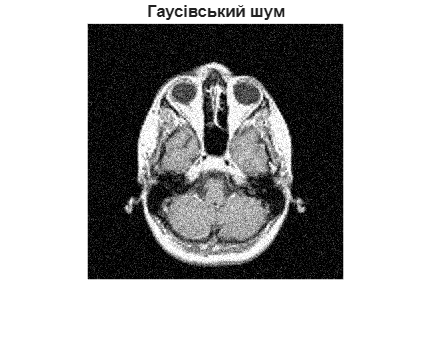

I_gauss = imnoise(I_best,'gaussian');
I_sp = imnoise(I_best,'salt & pepper');
I_poiss = imnoise(I_best,'poisson');
I_speckle = imnoise(I_best,'speckle');

figure

imshow(I_gauss)
title('Гаусівський шум')

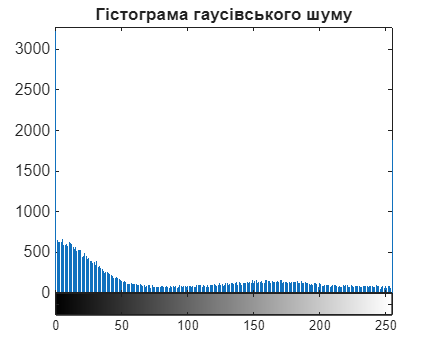

imhist(I_gauss)
title('Гістограма гаусівського шуму')

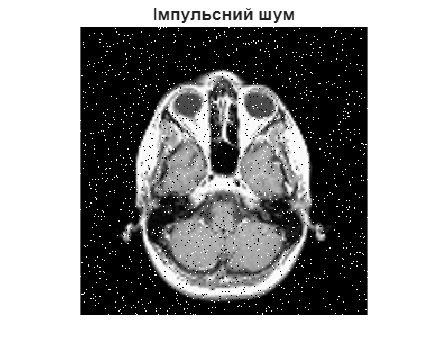


imshow(I_sp)
title('Імпульсний шум')

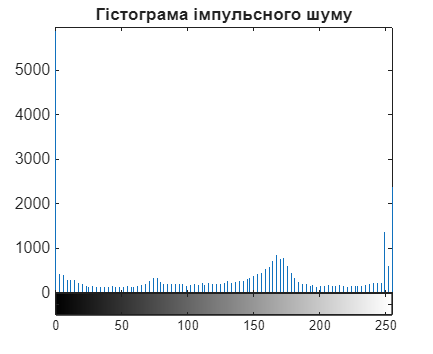

imhist(I_sp)
title('Гістограма імпульсного шуму')

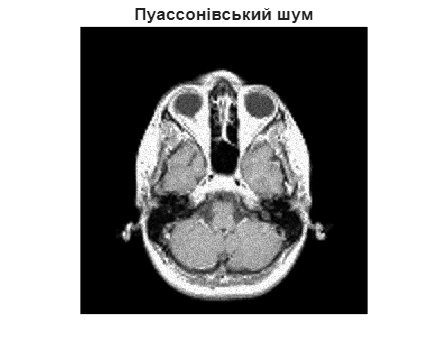


imshow(I_poiss)
title('Пуассонівський шум')

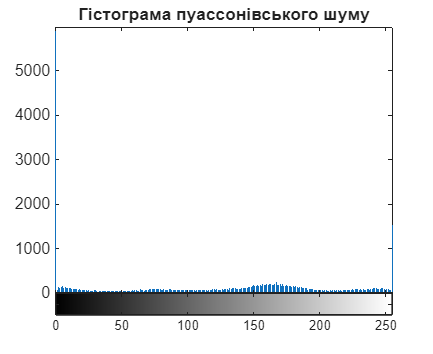

imhist(I_poiss)
title('Гістограма пуассонівського шуму')

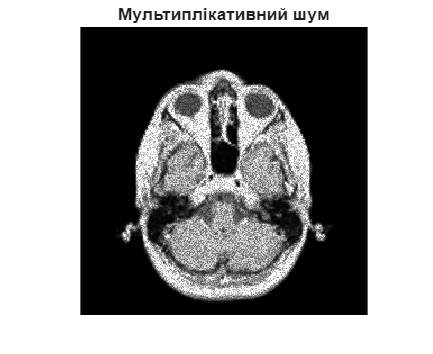


imshow(I_speckle)
title('Мультиплікативний шум')

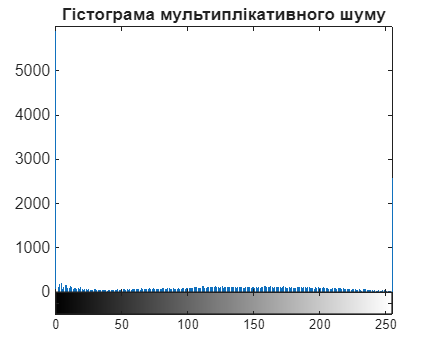

imhist(I_speckle)
title('Гістограма мультиплікативного шуму')

5) Провести фільтрацію зображень, зашумлених пуасонівським шумом, за допомогою наступних фільтрів: - медіанного фільтру (medfilt2);  - адаптивного фільтру Вінера (wiener2);  - фільтру усереднення (згладжувального) фільтру (fspecial та imfilter з  відповідним параметром).

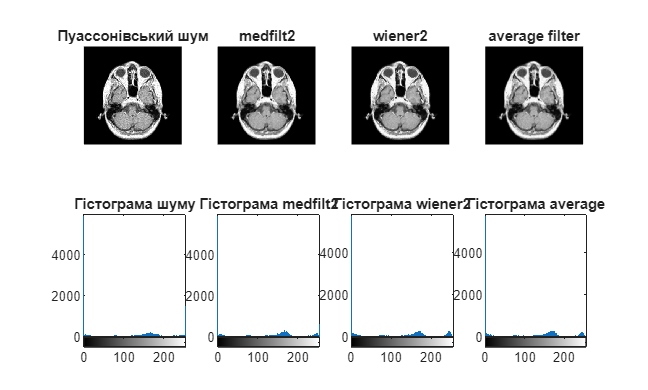

% медіанний фільтр
I_med = medfilt2(I_poiss);

% фільтр Вінера
I_w = wiener2(I_poiss,[3 3]);

% усереднюючий фільтр
h = fspecial('average',[3 3]);
I_avg = imfilter(I_poiss,h);

figure
subplot(2,4,1)
imshow(I_poiss)
title('Пуассонівський шум')
subplot(2,4,2)
imshow(I_med)
title('medfilt2')
subplot(2,4,3)
imshow(I_w)
title('wiener2')
subplot(2,4,4)
imshow(I_avg)
title('average filter')

subplot(2,4,5)
imhist(I_poiss)
title('Гістограма шуму')
subplot(2,4,6)
imhist(I_med)
title('Гістограма medfilt2')
subplot(2,4,7)
imhist(I_w)
title('Гістограма wiener2')
subplot(2,4,8)
imhist(I_avg)
title('Гістограма average')

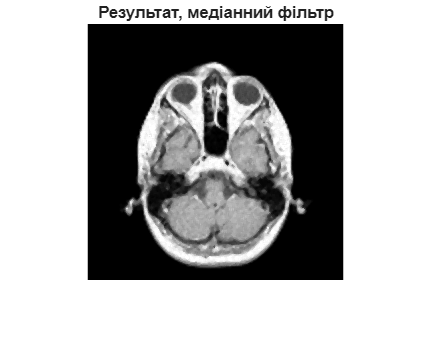


figure
imshow(I_med)
title('Результат, медіанний фільтр')

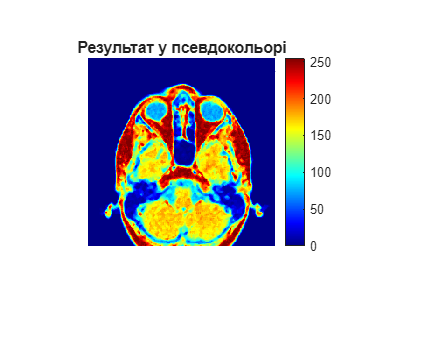

imshow(I_med)
colormap(jet)
colorbar
title('Результат у псевдокольорі')